# 2223-MA378 : Numerical Analysis 1

Lab 1 of Numerical Analysis 2: Experiments with polynomial interpolation 

- **Name: Niall Madden **[Change this to your name before submitting!!!!] 

- ID: `01234567` [Change this to your ID]

- Email:  `n.madden321@universityofgalway.ie` [*Change this to your email address*]

- Jan 2023

- Upload your script with solutions to Exercises 1, 2, 3 and 4 to Blackboard (2223-MA378... Labs ... Lab 1) by 5pm, Friday 3rd Feb.

## A MATLAB primer

You are using a MATLAB "Live script". This is a note-book type interface for MATLAB (a bit like Jupyter) that let's us combine text and MATLAB code. You can run pieces of code one section at time (click on "Run Section") or run the entire notebook.

### Everything is a vector

In Matlab, just about everything is a vector. In this lab, we are mainly interested in defining vectors the represent interpolation points. If, for example, we wanted to define a vector of points between 0 and 2, with gaps of 0.5, we could do in several ways.

The first is to just list all the points, using `[` and `] `to mark the start and end of the vector:

x = [0, .5, 1, 1.5, 2]

x =          0    0.5000    1.0000    1.5000    2.0000


The second is the use the colon notation, which is `start:step:end`.

x = 0:0.5:2

x =          0    0.5000    1.0000    1.5000    2.0000


Finally, there is a function called `linspace(), `which uses the syntax `linspace(start, end, number of points)`

x = linspace(0,2,5) % this one is more useful later

x =          0    0.5000    1.0000    1.5000    2.0000


MATLAB starts vectors at 1. So the first, 2rd and 4th elements of the vector we just defined are

x(1), x(2), x(4)

ans = 0

ans = 0.5000

ans = 1.5000

This means we have to be careful. In lectures, we've denoted the interpolation points $\{x_0, x_1, \dots, x_n\}$. But in MATLAB they are `[x(1), x(2), ..., x(n+1)]`.

### Vector arithmetic

One of MATLAB's great strengths is that it is easy to compute new vectors from old ones. For example, we can set 

y = cos(x)

y =     1.0000    0.8776    0.5403    0.0707   -0.4161


This has the effect of setting `y(1)=cos(x(1))`, `y(2)=cos(x(2))`, etc

More generally, we can combine vectors using the standard standard arithmetic operators: +, -, * and /. For any vector, $x$, the expression 

y = 2*x +3 

y =      3     4     5     6     7


sets `y(i) = 2*x(i) + 3`.

However, when we apply operators to pairs of vectors, we need to take a little care. First, of course, to add and subtract a pair of vectors, then need to have the same length. 

Multiplication and devision is a little more tricky. For example, mathematically, the expression $z=x*y$ would make no sense, because you can't multiply two (row) vectors). But we can use the "dot" operators: ".*" and "./" for multiplication and devision that is "entrywise".

That is `z = x.*y` sets `z(i) = x(i)*y(i)` for each $i$.

The dot operator also works for exponents: 

y = x.^2

y =          0    0.2500    1.0000    2.2500    4.0000


sets $y_i = x_i^2$

You can also apply standard mathematics functions, such as log(), exp(), sin(), cos(), abs(), etc. to vectors, and they will return vectors.

### Getting output (or not)

MATLAB is an interpretive language (like Python). You can run your code one line at a time. If a line ends with a semi-colon, then the result of the computation is not shown. If the vectors are very big, we usually end lines with a colon.

We can also check the value of the variable using the `disp()` function.

disp(x)

         0    0.5000    1.0000    1.5000    2.0000



### Plotting vectors

We can plot sets of points as follows. Assmung the vectors $x$ and $y$ are already defined, and are of the same length:

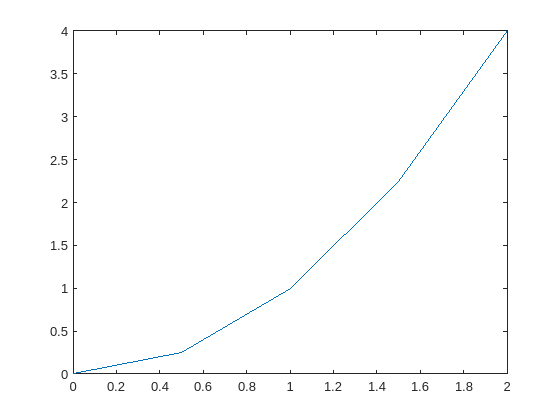

plot(x,y)

Often we want a little more control over:

- colour of the line

- line style (e.g., continuous, dashed)

- how points are displated

- line width.

See if you can work out why this line of code gives the output it does:

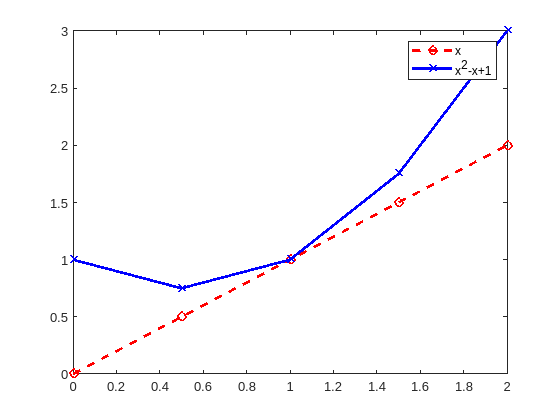

plot(x,x, 'r--o', x, x.^2-x+1, 'b-x', 'LineWidth',2)
legend('x', 'x^2-x+1')

## Defining the function that we will interpolate

In MATLAB, we can define functions using the "@" symbol. The syntax is:

Here the expession can be anything, but usually involves 

- the standard arithmetic operators: `+`, `-`, `*` and `/.` However, we will often write "`.*`" and "`./`" for multiplication and devision so that these are done "entrywise" for vectors.

- standard mathematics functions, such as l`og()`, `exp()`, `sin()`, `cos()`, `abs()`, etc.

In this first example, we will define $f(x)= e^{\cos(x/2)}$.

f = @(x)(exp(cos(x/2)));

Let's plot this on the interval $[-5,5]$.

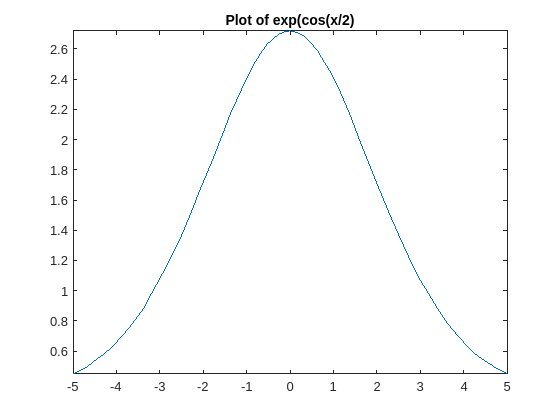

figure(1);
fplot(f,[-5,5]);
title('Plot of exp(cos(x/2)');

## Computing the interpolant

We could compute the interpolant to this function using Lagrange Interpolation. But MATLAB  has built-in functions for this, which we want to use.

The two main functions we use are:

- `polyfit(x,y,n)` which returns the coefficients of the polynomial of degree $n$ that inpterpolates the points. If we set `C = polyfit(x,y,n)` then `C` is a vector with $n+1$ entries. `C(1)` is the coeficient of $x^n$, `C(2)` is the coefficient of $x^{n-1}$, etc. However, we usually just want to compute C, and don't really care what the acual coefficents are.

- `polyval(C,X) `evaluates the polynomial represented by $C$. `Y = polyval(C,X)` would set $Y(i)$ to be the value of the polynomial at $X(i)$.

To compute the interpolant, we need to choose the end points $a$ and $b$:

a = -5; b = 5; % Approximate f(x) in the interval [a,b]=[-5,5].

Next, we choose $n$, the degree of the interpolating polynomial. Note that we'll have $n+1$ interpolation points.

n = 2;    % degree of the interpolation polynomial.

Next define the interpolation points:

x = linspace(a, b, n+1)  % the points x(1), x(2), ..., x(n+1)

x =     -5     0     5


Finally, define the vector of values to be interpolated.

y = f(x);   % the points to interpolate

Now that we have the data, we can actually do the interpolation

C = polyfit(x,y,n); % C is a vector containing the coefs of
                    % of the polynomial interpolant of f(x)

## Plotting the function and the interpolation

We'll define $X$ to be a vector of 1000 points between $a$ and $b$. This is just to help with plotting.

X = linspace(a, b, 100);   % X is a collection of 1000 in [a,b]

Finally we plot:

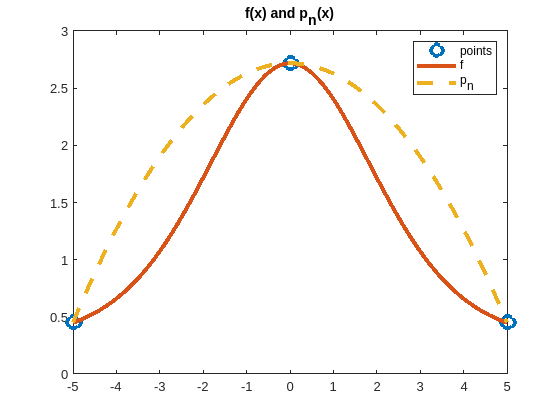

plot(x,y, 'o',...
   X, f(X), ...
   X, polyval(C,X), '--', ...
   'LineWidth',3, 'MarkerSize', 10)
legend('points', 'f', 'p_n');
title('f(x) and p_n(x)');

## Calculating and plotting the error

The Error at a given $x$ is $E(x) = |f(x)-p_n(x)|$. We'll define the vector of errors:

E = abs(f(X)-polyval(C,X));

The maximum value is:

disp(max(E))

    0.8281



We can also plot it:

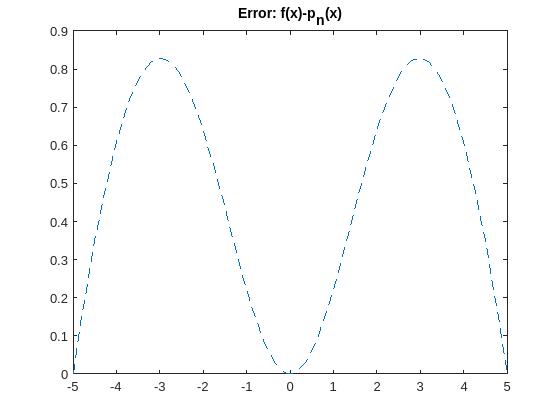

plot( X, E, '--')
title('Error: f(x)-p_n(x)');

## Exercise 1

Change the data at the top of this sheet to your name, ID, and email address. You are welcome to collaborate with classmates on this work. No need to include their data, however.

## Exercise 2

Copy the code for 

- defining $f$, $a$, $b$, $n$, $x$, and $y$ 

- interpolating $f(x)=e^\cos(x/2)$; that is computing $C$. 

- and for computing the maximum error; that is - compute $E$ and display its maximum value.

to here. **Then experiement to find the smallest value of **$n$** for which **$\max_{-5 \leq x \leq 5} f(x)-p_n(x) \leq 10^{-3}$. Ignore any warnings about the polynomial being "badly conditioned". Generally, you should note that, as $n$ increases, the maximum error decreases.

### Your solution goes here:

## Exercise 3

Exercise 2 (and the Weierstrass Interpolation theorem which I'll tell you about in class) might suggest that, for any $f$, we can make the error as small as we want by taking $n$ big enough. However, that is not true, at least if equally spaced points are used. 

To see this, change the definition of the function to $f(x) = \frac{1}{1+x^2}$. In MATLAB this is:

Demonstrate that, as $n$ increases, so too does the error. For example, determine the smallest value of $n$ for which the error is **greater** than 1. How about greater than 10? Or 100? or 1,000?

### Your solution goes here:

## Exercise 4

Instead of using equally spaced points, try choosing the points by hand. Start with $x_0=-5$, $x_1=0$, and $x_2=5$. Now choose $x_3$

and $x_4$ in a way that you think will reduce the error. And then $x_5$ and $x_6$ and so on. Using about 20 points you should be able to get the error close to $10^{-2}$.

*Tip: *Since the function is symmetric about $x=0$, just define, say, the points on $[-5,0]$ and then extend to $[-5,5]$ as follows:

*Another tip: *In previous exercises, we would choose $n$, and that would determine the values for $x$. In this Exercise, we are choosing the points in $x$, which determines the degree of the polynomial. So, after defining $x$, you need to set the value of $n$. That can be done as follows:

### Your solution goes here: 

## Bonus Exercise

You don't have to submit a solution to this part. But if you have time, please try it out.  

Although we won't cover it in class, Chebyshev showed that, in general, one should choose points given by the formula: $ x_i = \frac{b-a}{2}\cos\bigg( \frac{(i + \frac{1}{2})\pi}{n+1}\bigg) + \frac{b+a}{2}, \qquad \text{ for } \quad i=0, 1, \dots, n.$

Try this for various $n$ and test if it works. If you are interested, see Sections 8.4 and 8.5 of Suli and Mayers' "An Introduction to Numerical Analysis". Try this by writing some code which computes the interpolant for a given $n$ on the points obtained by the formula above. As $n$ increases, you should observe that the error decreases.

### Your solution goes here: